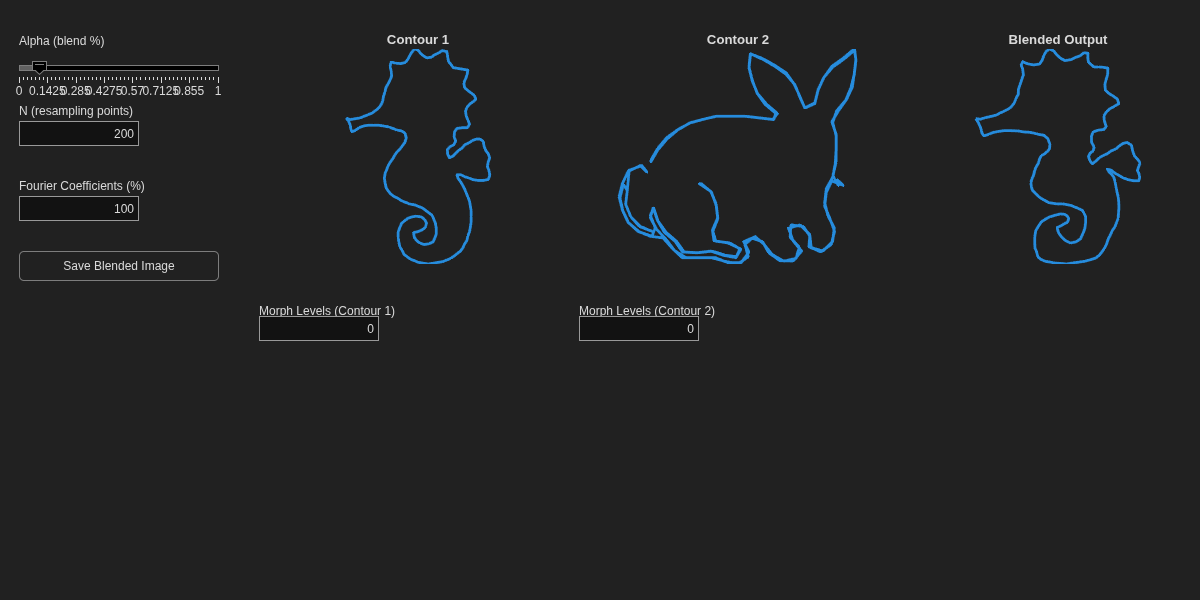

% Image path inputs
I1 = imread('seahorse.jpeg');
I2 = imread('bunny.jpeg');
s1 = size(I1);
s2 = size(I2);

% Convert to grayscale
if ismatrix(I1)
    I1 = im2gray(I1);
else
    I1 = rgb2gray(I1);
end
if ismatrix(I2)
    I2 = im2gray(I2);
else
    I2 = rgb2gray(I2);
end


function shapeBlendGUI(I1, I2)
% SHAPEBLENDGUI - Interactive Fourier shape blending GUI

    fig = uifigure('Name', 'Fourier Shape Blending', ...
                   'Position', [100 100 1200 600]);

    % Alpha slider
    uilabel(fig, 'Text', 'Alpha (blend %)', ...
        'Position', [20 550 120 20]);
    alphaSlider = uislider(fig, ...
        'Position', [20 530 200 3], ...
        'Limits', [0 1], ...
        'Value', 0.1, ...
        'ValueChangedFcn', @(s,~) updatePlot());

    % N resampling
    uilabel(fig, 'Text', 'N (resampling points)', ...
        'Position', [20 480 150 20]);
    NField = uieditfield(fig, 'numeric', ...
        'Position', [20 455 120 25], ...
        'Value', 200, ...
        'ValueChangedFcn', @(s,~) updatePlot());

    % Percentage of Fourier coefficients kept
    uilabel(fig, 'Text', 'Fourier Coefficients (%)', ...
        'Position', [20 405 200 20]);
    keepField = uieditfield(fig, 'numeric', ...
        'Position', [20 380 120 25], ...
        'Limits', [1 100], ...
        'Value', 100, ...
        'ValueChangedFcn', @(s,~) updatePlot());

    % Axes for images
    ax1 = uiaxes(fig, 'Position', [260 320 300 250]);
    ax1.Title.String = 'Contour 1';

    ax2 = uiaxes(fig, 'Position', [580 320 300 250]);
    ax2.Title.String = 'Contour 2';

    ax3 = uiaxes(fig, 'Position', [900 320 300 250]);
    ax3.Title.String = 'Blended Output';

    % Morph Level (Contour 1)
    uilabel(fig, 'Text', 'Morph Levels (Contour 1)', ...
        'Position', [260 280 200 20]);

    morphField1 = uieditfield(fig, 'numeric', ...
        'Position', [260 260 120 25], ...
        'Limits', [0 20], ...                % min/max levels
        'RoundFractionalValues', true, ...      % force integer
        'ValueDisplayFormat', '%.0f', ...       % display as integer
        'Value', 0, ...
        'ValueChangedFcn', @(s,~) updatePlot());

    % Morph Level (Contour 2)
    uilabel(fig, 'Text', 'Morph Levels (Contour 2)', ...
        'Position', [580 280 200 20]);
    morphField2 = uieditfield(fig, 'numeric', ...
        'Position', [580 260 120 25], ...
        'Limits', [0 20], ...
        'RoundFractionalValues', true, ...
        'ValueDisplayFormat', '%.0f', ...
        'Value', 0, ...
        'ValueChangedFcn', @(s,~) updatePlot());

    % Save Button
    saveBtn = uibutton(fig, 'push', ...
        'Text', 'Save Blended Image', ...
        'Position', [20 320 200 30], ...
        'ButtonPushedFcn', @(btn,~) saveBlended());




    updatePlot();

    function updatePlot()
        % Event listener to update the gui when inputs are changed
        alpha = alphaSlider.Value;
        N = round(NField.Value);
        keepPercent = keepField.Value / 100;

        morph1 = morphField1.Value;   
        morph2 = morphField2.Value;   
        
        % Recompute contours with morph strength
        contour1 = getContour(I1, morph1);
        contour2 = getContour(I2, morph2);


        % Preprocess contours, converting them into complex valued
        % representations needed for Fourier Transform and orienting them
        % in a consistent way
        z1 = preprocess(contour1, N);
        z2 = preprocess(contour2, N);

        % Apply Fourier Transform
        Z1 = fft(z1);
        Z2 = fft(z2);

        % Retain only a portion of the Fourier coefficients (indicated by
        % user) 
        K = round((N/2) * keepPercent);  % num coeficients to keep
        % create mask that only uses the part of the image that is within K
        mask = false(size(Z1));          
        mask(1:K) = true;
        mask(end-K+1:end) = true;

        % Zero out all high frequency components outside of the mask
        Z1(~mask) = 0;
        Z2(~mask) = 0;

        % Interpolate - This can be done in many different ways, we just
        % keep it simple by using a linear combination of the two fft's
        Z_blend = (1 - alpha) * Z1 + alpha * Z2;
        z_rec = ifft(Z_blend); % Reconstruct
        
        % Assume image size and normalize
        imgSize = [256 256];
        z = z_rec - mean(z_rec);
        z = z / max(abs(z));

        % Refit the complex contours into plotable x, y coordinates
        [x, y] = scaleToImage(z, imgSize);
        [x1, y1] = scaleToImage(z1, imgSize);
        [x2, y2] = scaleToImage(z2, imgSize);

        cla(ax1); cla(ax2); cla(ax3);

        % Plot blended image
        h = imgSize(1); % image height
        plot(ax1, x1, h-y1, 'LineWidth', 2); axis(ax1, 'equal'); axis(ax1, 'off');
        plot(ax2, x2, h-y2, 'LineWidth', 2); axis(ax2, 'equal'); axis(ax2, 'off');
        plot(ax3, x, h-y, 'LineWidth', 2); axis(ax3, 'equal'); axis(ax3, 'off');
    end

    function saveBlended()
        % Save the output image 
        % Capture blended output from ax3
        F = getframe(ax3);
        img = F.cdata;
    
        % Save as JPEG
        imwrite(img, 'blended_image.jpeg');
    
        % Optional message (non-blocking)
        uialert(fig, 'Blended image saved as blended_image.jpeg', 'Saved!');
    end

end

function contour = getContour(I, level)
    % getContour - Extracts the largest boundary contour from an image
    %
    % Inputs:
    %   I - input image
    %   level - indicates the amount of morphological processing to perform
    %
    % Outputs:
    %   contour - Nx2 array of [row, col] points of the largest boundary
    
    % Canny edges
    edges = edge(I, 'Canny');
    
    % Morphological functions to ensure boundary is closed
    se = strel('disk', 2);
    for i = 1:level
        edges = imdilate(edges, se);
        edges = imclose(edges, se);
    end
    
    % Fill interior
    filled = imfill(edges, 'holes');
    boundaryMask = bwperim(filled);
    
    % Extract contour points
    B = bwboundaries(boundaryMask); 
    [~, idx] = max(cellfun(@length, B)); % largest/outermost boundary
    contour = B{idx};
end



function z_resampled = preprocess(contour, N)
    % preprocess - process the contours to get consistency amongst the
    % contours, making them interpolatable.
    %
    % Inputs:
    %   contour - [row, col] coordinate list (y, x)
    %   N - number of points you want in the Fourier representation
    % 
    % Outpus:
    %   z_resampled - a complex-valued 1×N vector representing the contour

    % Extract x, y and create z
    x = contour(:,2);   % column = x
    y = contour(:,1);   % row = y
    z = x + 1i*y;

    % Ensure counterclockwise orientation
    if ispolycw(x, y)
        z = flip(z);
    end

    % Anchor the shape
    % Move the Left-most point to the start
    [~, idx_min] = min(real(z));   % smallest x
    z = circshift(z, -idx_min + 1);

    % Arc-length parameterization – better than uniform indexing because contour
    % points aren't evenly spaced. Using true distance along the curve gives a
    % smoother, more consistent sampling for the Fourier descriptors.
    d = abs(diff(z));             % distances between samples
    s = [0; cumsum(d)];           % cumulative arc length
    s = s / s(end);               % normalize to [0,1]

    % Resample at N equally spaced arc-length points
    s_new = linspace(0, 1, N);
    z_resampled = interp1(s, z, s_new, 'linear');

    % Translation normalization
    z_resampled = z_resampled - mean(z_resampled);

    % Scale normalization
    z_resampled = z_resampled / max(abs(z_resampled));


    % Re-anchor leftmost point -
    % This stabilizes orientation 
    [~, idx_min] = min(real(z_resampled));
    z_resampled = circshift(z_resampled, -idx_min + 1);
end




function [x,y] = scaleToImage(z, imgSize)
    % scaleToImage - aps a normalized complex contour into pixel coordinates
    %
    % Inputs:
    %   z - complex valued contour representation
    %   imgSize - size of output image
    % 
    % Outpus:
    %   [x, y] - x and y coordinates of the scaled contour

    % Get x and y coordinates
    x = real(z);
    y = imag(z);

    % Scale to fit inside the image 
    minX = min(x);  maxX = max(x);
    minY = min(y);  maxY = max(y);

    width  = maxX - minX;
    height = maxY - minY;

    % Compute scale factor to fit within image
    s = 0.9 * min(imgSize(2) / width, imgSize(1) / height); % 0.9 = margin

    x = (x - minX) * s;
    y = (y - minY) * s;

    % Now center inside the image
    X_center = (imgSize(2) - max(x)) / 2;
    Y_center = (imgSize(1) - max(y)) / 2;

    x = x + X_center;
    y = y + Y_center;

end




shapeBlendGUI(I1, I2);